A script to calculate the minimal amount of mannose to initialize the system with by solving a system of equations

v = args.p2.v;

%v.initialpop = 1;

growthrate = 0.01;
ngam = v.NGAM;
gam = v.GAM;
biomass0 = v.initialpop;
glcvmax = 1;
manvmax = 1000000;
celvmax = v.kcat_cel * 60 * 60; %convert to h^-1
glckm = v.km_glc;
mankm = v.km_man;
celkm = v.km_cel;
cel0 = v.initcellulose;
glc0 = 0;
alpha = v.alpha;


%get the amount of growth per unit sugar (as in y = mx+b, where b accounts
%for the maintenance)
v.alpha = 0;
v.maintRxnAsObjective = false;

ex.man = stridx('D-mannose exchange',args.p2.model.rxnNames,false);
ex.glc = stridx('D-glucose exchange',args.p2.model.rxnNames,false);

%growth per glc
model = prepareYeastGEMModel('model',args.p2.model,'v',v);

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 10680 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 5340 gtp[c] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	10680 adp[c] + 5340 gdp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51

model.lb(ex.man) = 0;
uptakes.glc = (0.4:.1:3)';
growthrates.glc = zeros(size(uptakes.glc));
for i = 1:length(uptakes.glc)
    model.lb(ex.glc) = -uptakes.glc(i);
    opt = optimizeCbModel(model);
    growthrates.glc(i) = opt.f;
end

%format as Y = XB
Xglc = horzcat(ones(size(uptakes.glc)),uptakes.glc);
Bglc = Xglc\growthrates.glc;
glcmaint = Bglc(1) %-0.0087

glcmaint = -0.0087

growthperglc = Bglc(2) %0.0248

growthperglc = 0.0248

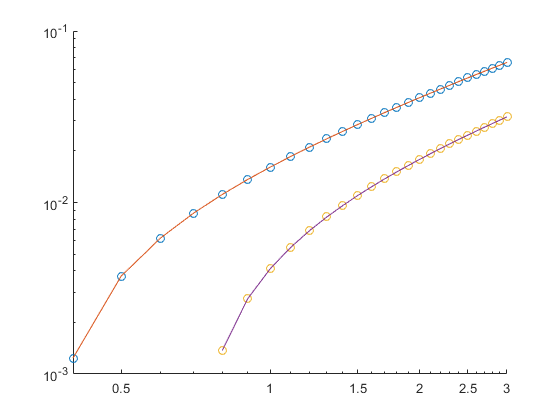



%growth per mannose
uptakes.man = (0.8:.1:3)';
model.lb(ex.glc) = 0;
growthrates.man = zeros(size(uptakes.man));
for i = 1:length(uptakes.man)
    model.lb(ex.man) = -uptakes.man(i);
    opt = optimizeCbModel(model);
    growthrates.man(i) = opt.f;
end

%format as Y = XB
Xman = horzcat(ones(size(uptakes.man)),uptakes.man);
Bman = Xman\growthrates.man;

%plot to confirm we did it right:
ycalc1 = Bglc(1) + (Bglc(2) * uptakes.glc);
ycalc2 = Bman(1) + (Bman(2) * uptakes.man);
figure();
hold on;
scatter(uptakes.glc,growthrates.glc);
plot(uptakes.glc,ycalc1)
scatter(uptakes.man,growthrates.man);
plot(uptakes.man,ycalc2)

set(gca,'xscale','log');
set(gca,'yscale','log');

hold off;


manmaint = Bman(1) %-0.0096

manmaint = -0.0096

growthperman = Bman(2) %0.0137

growthperman = 0.0137


%try a simple version
syms man0 mandelta0 deltabiomass0;

es.manispos = man0 > 0;
es.limitedmannose = mandelta0 <= man0;
es.manuptake0 = man0 * biomass0 * manvmax / (man0 + mankm) >= mandelta0;

es.manuptake0 = mandelta0 == man0;

%eq.growth0 = ((-mandelta0 * atpperman) - (ngam * biomass0)) * growthperatp * biomass0 == deltabiomass0;
es.growth0 = (mandelta0 * growthperman) - manmaint == deltabiomass0;

es.didgrow = deltabiomass0 > 0;
es.didgrow = deltabiomass0 == biomass0 * 0.01;

S = solve([es.manispos, es.manuptake0, es.growth0, es.didgrow],'ReturnConditions',true)

S = struct with fields:
    deltabiomass0: [0×1 sym]
             man0: [0×1 sym]
        mandelta0: [0×1 sym]
       parameters: [1×0 sym]
       conditions: [0×1 sym]


S.man0 %0.0284 mmol. If mannose weighs 180.156 g/mol, this is 0.0051 g mannose per g biomass

 
ans =
 
Empty sym: 0-by-1
 


S.mandelta0 %0.0284

 
ans =
 
Empty sym: 0-by-1
 


S.deltabiomass0

 
ans =
 
Empty sym: 0-by-1
 


S.parameters

 
ans =
 
Empty sym: 1-by-0
 


S.conditions

 
ans =
 
Empty sym: 0-by-1
 


%try the full version
syms r man0 glc1 enz0 mandelta0 glcdelta1 biomass1 deltabiomass1 deltabiomass0;

%es.manispos = man0 > 0;
es.manrelativetobio = man0 == r * biomass0;
es.manuptake0 = man0 * biomass0 * manvmax / (man0 + mankm) >= mandelta0;
es.growth0 = (mandelta0 * growthperman) - manmaint == deltabiomass0;
es.sumgrowth0 = biomass1 == biomass0 + deltabiomass0;
es.didgrow0 = deltabiomass0 == biomass0 * growthrate;
%eq.manuptake0 = mandelta0 == man0;
%eq.growth0 = ((-mandelta0 * atpperman) - (ngam * biomass0)) * growthperatp * biomass0 == deltabiomass0;
es.enzprod0 = enz0 == deltabiomass0 * alpha;
es.cellulolysis0 = glc1 == glc0 + (enz0 *celvmax* cel0 / (celkm + cel0));

es.glcuptake1 = glc1 * biomass1 * glcvmax / (glc1 + glckm) >= glcdelta1;
es.growth1 = (glcdelta1 * growthperglc) - glcmaint == deltabiomass1;
es.didgrow1 = deltabiomass1 == biomass1 * growthrate;

S = solve([es.manrelativetobio,...
    es.manuptake0,...
    es.growth0,...
    es.sumgrowth0,...
    es.didgrow0,...
    es.enzprod0,...
    es.cellulolysis0,...
    es.glcuptake1,...
    es.growth1,...
    es.didgrow1],...
    'ReturnConditions', true)

S = struct with fields:
         biomass1: [1×1 sym]
    deltabiomass0: [1×1 sym]
    deltabiomass1: [1×1 sym]
             enz0: [1×1 sym]
             glc1: [1×1 sym]
        glcdelta1: [1×1 sym]
             man0: [1×1 sym]
        mandelta0: [1×1 sym]
                r: [1×1 sym]
       parameters: [1×1 sym]
       conditions: [1×1 sym]



%%%%%%

% eq.glcuptake1 = glc1 * biomass1 * glcvmax / (glc1 + glckm);
% eq.manuptake0 = man0 * biomass0 * manvmax / (man0 + mankm) == mandelta0;
% eq.summan0 = man1 == man0 - mandelta0;
% eq.manuptake1 = man1 * biomass1 * manvmax / (glc1 + mankm);
% eq.growth0 = ((-mandelta0 * atpperman) - (ngam * biomass0)) * growthperatp * biomass0 == deltabiomass0;
% eq.sumbio0 = biomass1 == biomass0 + deltabiomass0;
% eq.enzprod0 = deltabiomass0 * alpha == enz0;
% eq.glcprod0 = enz0 * celvmax * cel0 / (cel0 + celkm) == glc1;
% eq.growth1 = ((eq.manuptake1 * atpperman) + (eq.glcuptake1 + atpperglc) - (ngam * biomass1)) * growthperatp * biomass1 == deltabiomass1;
% eq.didgrow = deltabiomass1 > 0;

% S = solve([eq.didgrow, eq.summan0, eq.glcuptake1, eq.sumbio0, eq.manuptake0, eq.manuptake1, eq.growth0, eq.enzprod0, eq.glcprod0, eq.growth1],...
%     'ReturnConditions', true)

S.parameters

$$ans = z_{1}$$

S.conditions

$$ans = -\frac{4093271342708159514267}{11696900678299354726400}\leq \frac{415432292507634318183203011454136135595004713940175}{9105637424003606234568162765301334696059962968952692277248}\wedge -\frac{45376410194469112859}{64832550556161990656}\leq \frac{387602883570881478450185729581890625\,z_{1}}{21267647932558653966460912964485513216\,\left(\frac{4980620899901579\,z_{1}}{36893488147419103232}+\frac{1}{1000000000000000}\right)}$$

%0.0284 <= ((1e6 * z)/(z + 1e-16)) ^ 0.0578 <= 0.7197
% 
S.r

$$ans = z_{1}$$

S.man0  

$$ans = \frac{4980620899901579\,z_{1}}{36893488147419103232}$$

S.glc1 

$$ans = \frac{25807468948100629625244782650779}{77101941569880197488886434229670379520}$$

S.enz0 

$$ans = \frac{6375194751874021}{151115727451828646838272}$$

S.mandelta0 

$$ans = -\frac{45376410194469112859}{64832550556161990656}$$

S.glcdelta1 

$$ans = -\frac{4093271342708159514267}{11696900678299354726400}$$

S.biomass1 

$$ans = \frac{643894669939276133}{4722366482869645213696}$$

S.deltabiomass1 

$$ans = \frac{643894669939276133}{472236648286964521369600}$$

S.deltabiomass0

$$ans = \frac{6375194751874021}{4722366482869645213696}$$

## Solve as an optimization problem

%try a simple version
r = optimvar('r');
man0 = optimvar('man0');
mandelta0 = optimvar('mandelta0');
deltabiomass0 = optimvar('deltabiomass0');

x.r = 0.05;
x.man0 = 1;
x.mandelta0 = 1;
x.deltabiomass0 = 0.01 * biomass0;

prob = optimproblem;
prob.Objective = man0;
prob.Constraints.c1 = man0 == r  * biomass0;
prob.Constraints.c2 = man0 * biomass0 * manvmax / (man0 + mankm) >= mandelta0;
prob.Constraints.c3 = (mandelta0 * growthperman) - manmaint == deltabiomass0;
prob.Constraints.c4 = deltabiomass0 == biomass0 * 0.01;
prob.Constraints.c5 = man0 >= 0;
prob.Constraints.c6 = mandelta0 <= man0;
sol = solve(prob,x)


Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


sol = struct with fields:
    deltabiomass0: 1.3500e-06
             man0: 4.0013e-07
        mandelta0: -0.6999
                r: 0.0030
